# Homework 3 (45pt)

*Type your NAME (first, last) and ID below*

Boxuan Zhang 95535906

## Homework instructions:

- Write your **name** and **student ID** in the above section.

- Make sure you have downloaded all related files from Canvas.

- Write ALL answers and your MATLAB code in this livescript file, make sure you write your code in the code block and test it before submission.

- Usually you should only submit this livescript (.mlx file) with all your answers and code. However, if you have additional .m files, please make sure to put them in the same folder.  

- Rename this livescript as "***Math9_HW3_(your name)_(your ID).mlx***" before submission!

- You are responsible for checking UCI email and course Canvas page regularly for potential updates.

**Note:** Throughout this homework, please define the functions as ***in-script***, i.e. at the end of this live script file. Do not define functions in additional .m files. 

## Problem 1. Estimate the Area of an Ellipse (10pt)

Use Monte Carlo Method to estimate the area of an ellipse, which is described by the equation: $\frac{x^2 }{1^2 }+\frac{y^2 }{2^2 }=1$. 

**(1pt) **1. In the code block below, defince the function handle " f " as the ellipse, and run the provided code for visualization:

***hint1:*** `fimplicit(`[`f`](https://www.mathworks.com/help/matlab/ref/fimplicit.html#bvds9d6-1-f)`)` plots the implicit function defined by `f(x,y) = 0` over the default interval `[-5 5]` for `x` and `y`.

***hint2:*** you need to rewrite the equation $\frac{x^2 }{1^2 }+\frac{y^2 }{2^2 }=1$ to match the `f(x,y) = 0 format.`

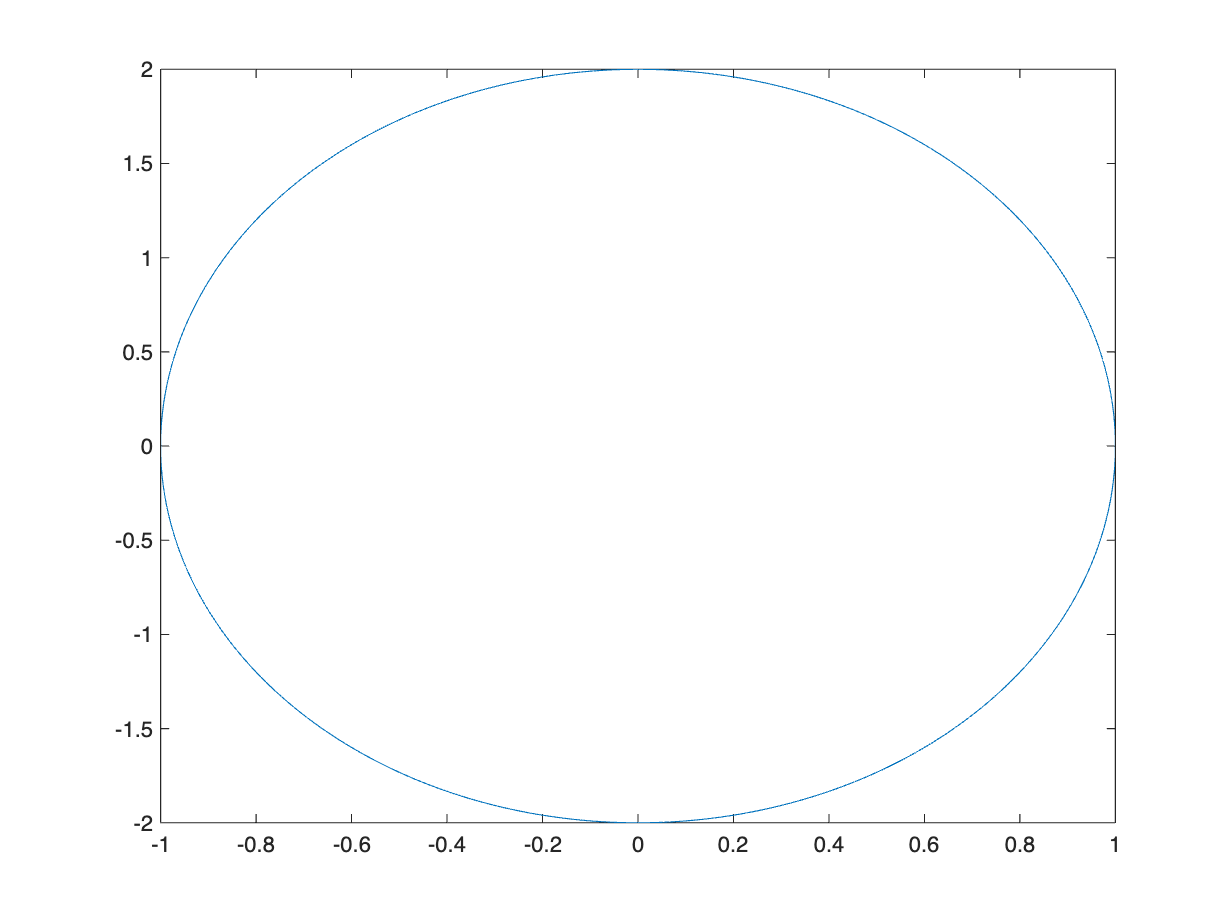

% define function handle
f = @(x,y) [(x.^2)/1] + [(y.^2)/2^2] - 1;
% run the code for visualization (provided code)
fimplicit(f)

**(4pt) **2. Use Monte Carlo Method to estimate the area of a ellipse (total number of points = 2000). Compare your result to $2\pi \;$by calculating the absolute error.

***hint 1:*** estimate the ellipse's area in the first quadrant -- inside a rectangle of height 2 and width 1, and multiply by 4

***hint 2:*** generate random points which: x-coordinates are random number from 0 to 1,  y-coordinates are random number from 0 to 2, 

***hint 3:*** if a point `(x,y)` satisfies $\frac{x^2 }{1^2 }+\frac{y^2 }{2^2 }<1$, then it is inside the ellipse.

**(2pt) **3. (Similar to the example in the lecture note) Plot these random points, color the points inside to blue and points outside to red.

**(3pt) **4. Write MATLAB code (without defining new functions) to: change N from 100 to 5000 with stepsize = 100, find the minimal N such as the absolute error is less than 0.01.

% write your codes here

% 2. estimate the ellipse's area
N = 2000;
x = rand(N,1);
y = 2 * rand(N,1);

inside = (f(x,y)+1) <= 1;
outside = (f(x,y)+1) > 1;

num_inside = sum(inside);
area = (num_inside / N) *2*1;
est_area = area*4;
abs_error = abs(est_area - 2*pi)

abs_error =    0.071185307179586


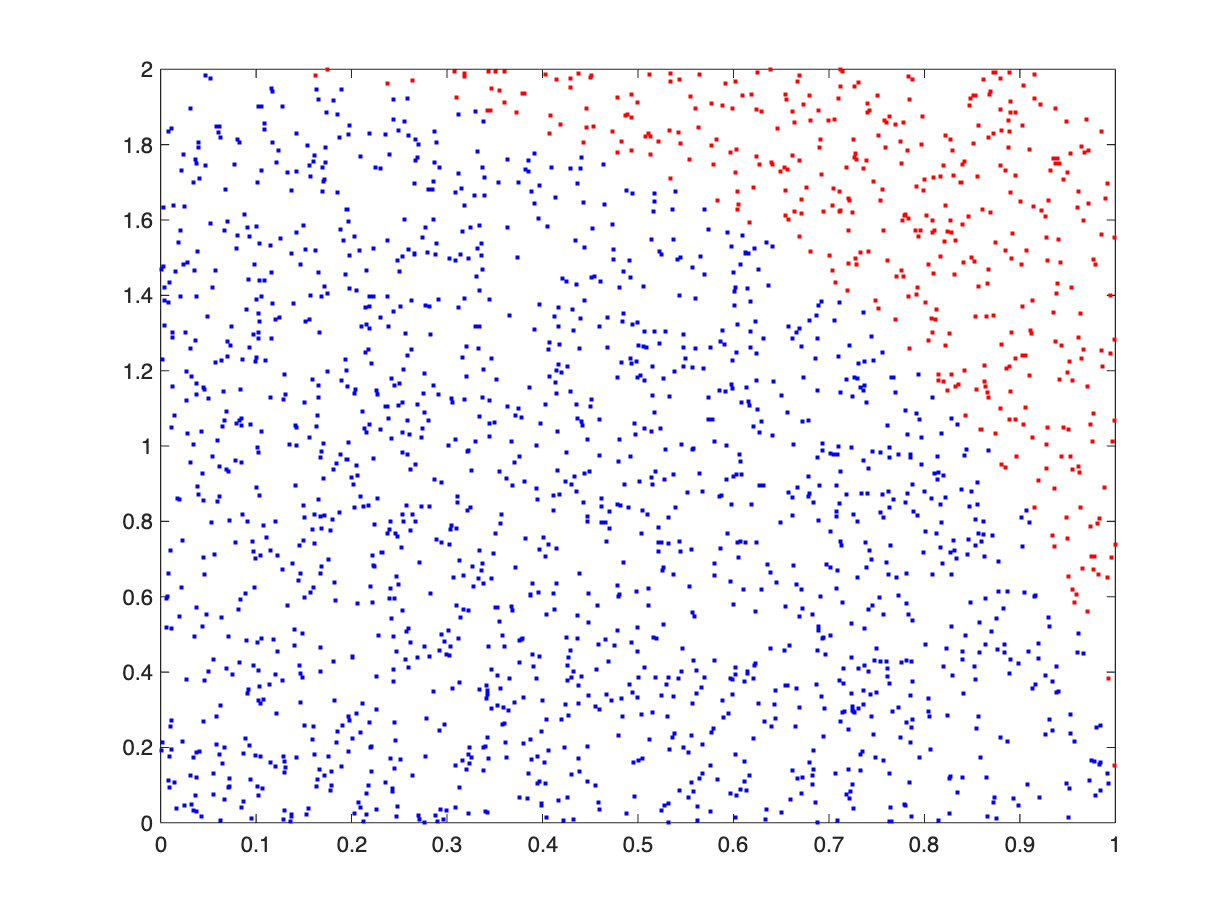

% 3. plot
plot(x(inside), y(inside), 'b.')
hold on
plot(x(outside), y(outside), 'r.')
hold off

% 4. find the minimal N
N = 100:100:5000;
min_v = [];
for i = N
    x = rand(i,1);
    y = 2 * rand(i,1);
    
    inside = (f(x,y)+1) < 1;
    
    num_inside = sum(inside);
    area = (num_inside / i) *2*1;
    est_area = area*4;
    abs_error = abs(est_area - 2*pi);
    if abs_error < 0.01
        min_v = [min_v, i];
    end
end
min = min_v(1);
for i = 1:length(min_v)
    if min_v(i) < min
        min = min_v(i);
    end
end
min

min =         3000


## Problem 2. The weighted random walk (22pt)

In the lecture, we introduced the simple 1D random walk where the random walker can either goes left or right with equal probability 0.5. In the weighted random walk, random walker in each step can choose to move righward (i.e. position +1) with probability $p$ ($0<p<1$) and move leftward (position -1) with probability $\left(1-p\right)$.  Follow the instructions below:

**(5pt) **1. Define the in-script function named "`rw_weight(n,p)"` with the input **steps number **$n$, and **right-ward probability **$p$, and ouput the row vector (length $\left(n+1\right)$) recording the initial position 0 (as the first element), and all the positions in $n$ steps in one simulation (each output is now called one trajectory).

**(7pt) **2. In the code blocks below, simulate $N=20$ trajectories with $p=0\ldotp 6$ and $n=500$ steps each with the defined function, and store in the a $N\times \left(n+1\right)$ matrix named "`traj"`. Plot the trajectories using `plot` function, name the x-axis "step" and y-axis "positions".

**(8pt) **3. If a series of probabilities have been select as $p=0\ldotp 05:0\ldotp 1:0\ldotp 95$. Now generate a matrix named `data` and its **i-th column** stores two values -- **the mean **and** standard deviation** of the random walker's position (which is a random number) after $n=100$ steps with parameter $p\left(i\right)$, calculated from $N=200$ simulations (i.e. in each simulation the random walker moves 100 steps with right-ward probability $p\left(i\right)$, and then we have one ending position. After 200 simulations, we will have 200 ending positions, then we can calculate their mean and standard devistion). Then use the codes below to plot matrix `data`, which displays how the ending postions of random walker changes with repect to rightward-moving probability. Name the x-axis "probability p" and y-axis "ending position".` (``h`***int*****:** use the function "`mean"` and "`std"` in MATLAB to calculate the mean and standard devistion.)

**(2pt) **4. What do you observe from the plot (in 3.)? And how to explain your observation? 

***Write your answer here.***

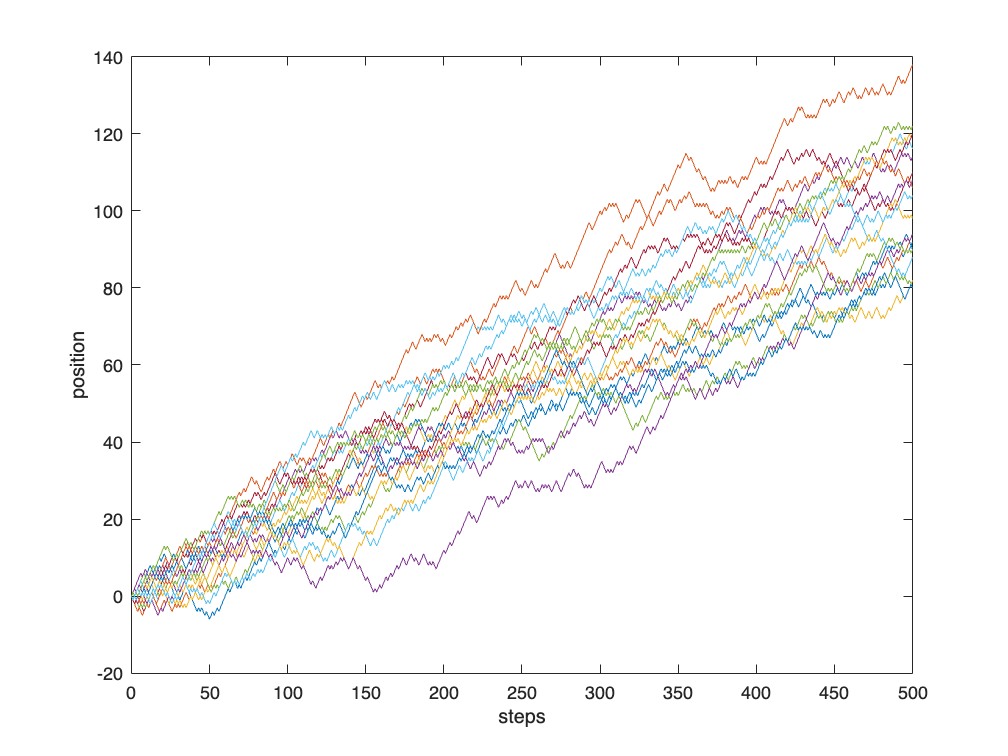

% write your codes below 

% 2.
N = 20;
n = 500;
p = 0.6;
traj = zeros(1,n+1);
for i = 1:N
    traj(i,:) = rw_weight(n,p);
end

plot(0:n, traj)
xlabel('steps')
ylabel('position')

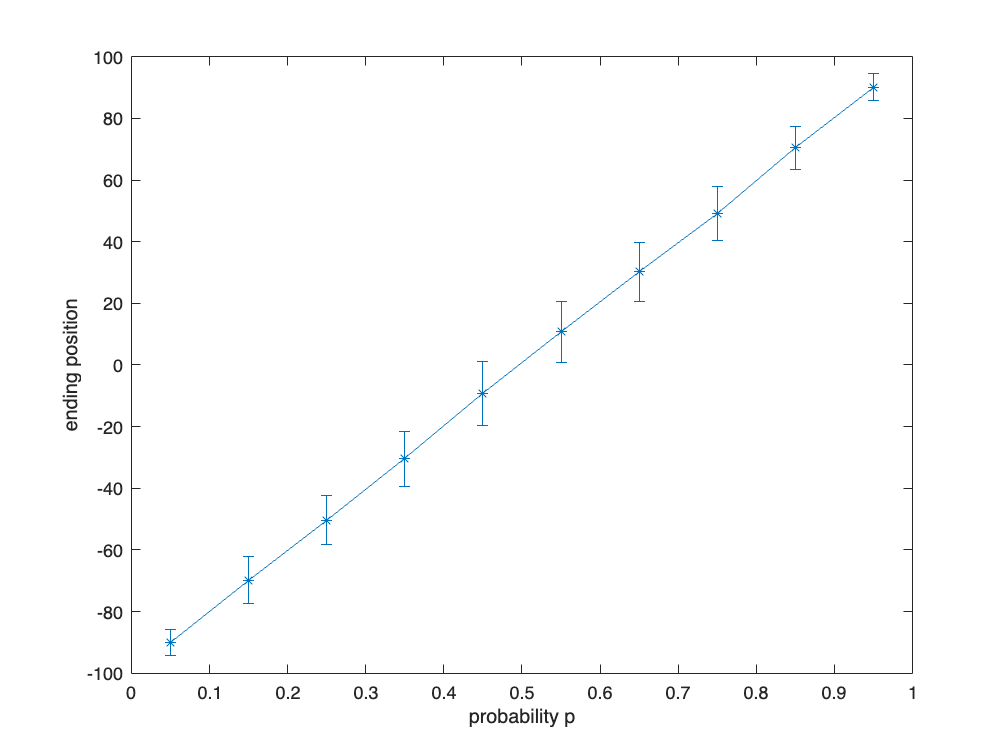

% 3.
p = 0.05:0.1:0.95;
N = 200;
n = 100;

data = zeros(2, length(p));
for i = 1:length(p)
    final_positions = zeros(1, N);
    for j = 1:N
        traj = rw_weight(n, p(i));
        final_positions(j) = traj(end);
    end

    data(1,i) = mean(final_positions);
    data(2,i) = std(final_positions);
    
end
% provided codes
errorbar(p,data(1,:),data(2,:),'*-')
xlabel('probability p')
ylabel('ending position')

% The plot shows a nearly linear relationship between x and y, with y increasing as x increases. 
% The standard deviation is largest when the probability around 0.5 and it is much
% smaller when the probability is less than 0.1 and greater than 0.9.

## Problem 3. The secant method for root finding (13pt)

Instead of using numerical derivatives, a more common approach to get rid of the derivative function in Newton's method for root finding of nonlinear equation $f\left(x\right)=0$ is the [secant method](https://en.wikipedia.org/wiki/Secant_method), with the recursive formula defined as


$$x_k =x_{k-1} -f\left(x_{k-1} \right)\frac{x_{k-1} -x_{k-2} }{f\left(x_{k-1} \right)-f\left(x_{k-2} \right)}$$
 

with the initial value of $x_1$ and $x_0$ near the root provided by the user. Now follow the instructions below:

**(6pt) **1. Define the in-script function "`secant(f,x0,x1,thresh)" `with input nonlinear function handle `f`, two initial values for iteration `x0` and `x1`, and denotes the `threshold` for absolute value of function to stop iteration. The function ouput x which is the approximated root by secant method.

**(2pt) **2. In the code block below, plot the function $f\left(x\right)={\left(\sqrt{\left|x\right|}+1\right)e}^{-x} -x^3 \sin \left(x\right)+x$  in the interval $\left\lbrack 0,2\right\rbrack$. You should follow the plotting codes above to add x and y axis labels this time. **Hint:** use the "`fplot"` function.

**(3pt) **3. In the code block below, call the secant method function to solve $f\left(x\right)={\left(\sqrt{\left|x\right|}+1\right)e}^{-x} -x^3 \sin \left(x\right)+x=0$ with appropriate initial values you observed from plot. 

**(2pt) **4. Check the correctness by calling the matlab function [fzero](https://www.mathworks.com/help/matlab/ref/fzero.html?s_tid=doc_ta), calculate the error.

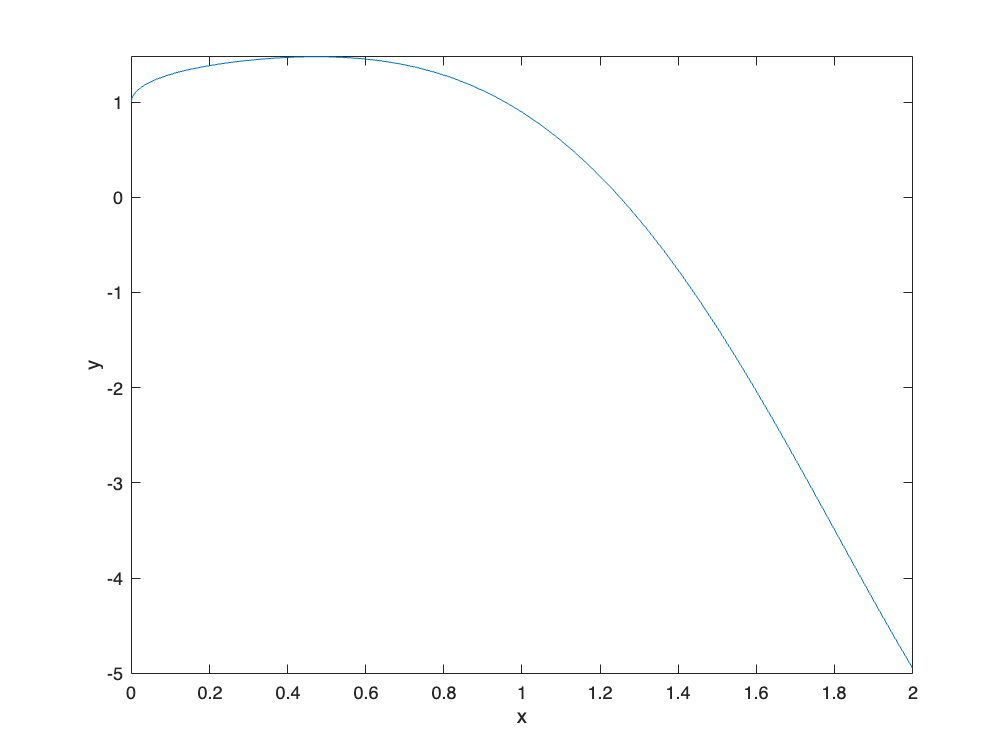

% write your codes below 
% 2. 
f = @(x) (sqrt(abs(x))+1).*exp(-x) - (x.^3) .* sin(x) + x;
fplot(f,[0,2]);
grid on
xlabel('x')
ylabel('y')
grid off

% 3.
x0 = 0.2;
x1 = 1.6;
thres = 1e-6;
x = secant(f,x0,x1,thres)

x =    1.250734985658863


% 4. 
true_value = fzero(f,x0);
error = abs(x-true_value)

error =      4.114525253839929e-08


## **Reference and Acknowledgement**

*You may list all the materials you referred to (including online materials and papers) and acknowledge the people who helped you in this section.*

## **Other Comments (optional)**

*You are welcome to leave your course-related comments here (lecture, homework, discussion session, etc.), you can also leave your comments in the Ed discussion panel or via email.*

## Define all the functions below

% define your functions here
function v = rw_weight(n, p)
    position = 0;
    for i = 2:n+1
        step = rand < p;
        position(i) = position(i-1) + 2*step-1;
    end
    v = position;
end


function x = secant(f, x0, x1, thres)
    while abs(f(x1))>thres
        x2 = x1-f(x1)*((x1-x0)/(f(x1)-f(x0)));
        x0 = x1;
        x1 = x2;
    end
    x = x1;

end